# Lesson 5

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Understand datatypes in MATLAB

- Understand character arrays and strings in MATLAB

- Understand Object Oriented Programming in MATLAB 

# Data Types

There are several basic data types in MATLAB:

- int8, int16, int32, int64

- uint8, uint16, uint32, uint64

- single, double

- logical

- string, char

- cell arrays

You can get the data type of a variable using the class function.

 a = 10;
 class(a)

ans = double

 b = int8(a);
 class(b)

ans = int8

##  Data Type Sizes

Different data types take up different amounts of space in your memory and hard drive.  Let's take a look at some standard sizes in MATLAB.

 clear
 A = randn(1,'double');
 B = randn(1,'single');
 C = true(1);
 D = 'D';
 E = int16(1);
 whos % lists all the variables in the workspace along with their size, bytes, and types

  Name      Size            Bytes  Class      Attributes

  A         1x1                 8  double               
  B         1x1                 4  single               
  C         1x1                 1  logical              
  D         1x1                 2  char                 
  E         1x1                 2  int16                



If your data is getting to large, it can help to cast as a single. Logicals take up a whole byte.  Surprising?

## Different Interpretations

Be careful with what data types you feed into built in functions.  MATLAB will have different responses to different types

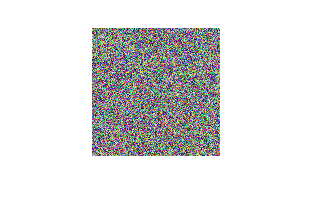

 imshow( uint8( 255*rand(128,128,3) ) )

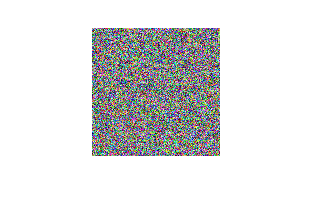

 imshow( double( 255*rand(128,128,3) ) )

## Overflow and Underflow

When we use floating point (singles and doubles), we are trying to represent real numbers. Unfortunately, there will be some spacing between representable numbers. Let's take a look.

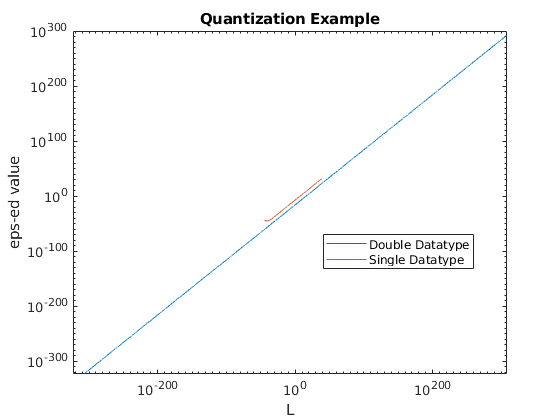

L = logspace(-308,308,4096);  % a large range of values, defaults to double type

figure
% eps shows the distance between the input and the next closest floating point value
loglog(L, eps(L), 'DisplayName', 'Double Datatype') 
hold on
loglog(single(L), eps(single(L)), 'DisplayName', 'Single Datatype')
legend('Location', 'best')
xlabel('L'), ylabel('eps-ed value'), title('Quantization Example')

As the plot proves, doubles have a much larger extent (they can be used to represent much larger values) as well as more precision at each point.  Let's see how this applies in practice.

eps(double(1))

ans = 2.2204e-16

(1 + 0.5001*eps(1)) - 1

ans = 2.2204e-16

(1 + 0.5*eps(1)) - 1

ans = 0

1 + 1e16 == 1e16

ans = logical
   1


single(10^50)

ans = single
Inf

single(10^-50)

ans = single
0

uint8(256)

ans = uint8
255

int8(-129)

ans = int8
-128

These are all effects of quantization, and should be kept in mind when dealing with very small / large values as well as with very small increments. You will explore quantization more thoroughly in your Digital Signal Processing course.

## Cell Arrays

Cell arrays are arrays whose elements can contain any type of MATLAB object. As such they are useful when you have data that is not well structured. However, they are also relatively slow and hard to deal with compared to matrices, which require a uniform dataype throughout. As such, you should use them sparingly.

courses = { '' 'Modern Physics' 'Signals and Systems' 'Complex Analysis', ...
            'Drawing and Sketching for Engineers'; ...
            'Grades', 70 + 3*randn(132,2), single(80 + 3*randn(41,1)), 40 + 3*randn(20,1), uint16(100*ones(29,1));...
            'Teachers', {'Debroy';'Yecko'}, {'Fontaine'}, {'Smyth'}, {'Dell'}}

courses = 3×5 cell array
    {0×0 char  }    {'Modern Physics'}    {'Signals and Systems'}    {'Complex Analysis'}    {'Drawing and Sketching for Engineers'}
    {'Grades'  }    {132×2 double    }    {41×1 single          }    {20×1 double       }    {29×1 uint16                          }
    {'Teachers'}    {  2×1 cell      }    { 1×1 cell            }    { 1×1 cell         }    { 1×1 cell                            }


courses(1,2)

ans = 1×1 cell array
    {'Modern Physics'}


courses{1,2}

ans = 'Modern Physics'

courses{2,2}(3:5,1)

ans =    71.7132
   65.5750
   70.5875


courses(3,2)

ans = 1×1 cell array
    {2×1 cell}


courses{3,2}

ans = 2×1 cell array
    {'Debroy'}
    {'Yecko' }


courses{3,2}{1}(1)

ans = 'D'

# Character Arrays and Strings

## Character Array

clear

myString =  'Hello World!'; % this is a character vector
herString = 'Hello, World';
char_array = [myString; herString] % this is a character array

char_array = 2×12 char array
    'Hello World!'
    'Hello, World'



whos

  Name            Size            Bytes  Class    Attributes

  char_array      2x12               48  char               
  herString       1x12               24  char               
  myString        1x12               24  char               



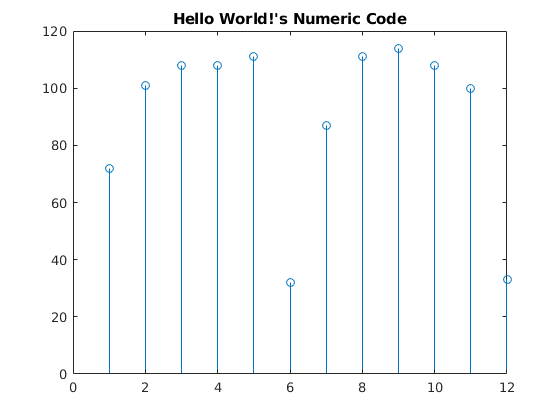

figure
stem(uint16(myString))
title([myString '''s' ' Numeric Code'])

## sprintf

The *sprintf* function is useful in formatting strings to be output.

numberOfStudents = 20;
section = 'B';
averageGrade = mean(40 + randn(numberOfStudents,1));
sprintf('There are %d students in physics section %s with an average grade of %0.2f',...
        numberOfStudents,section,averageGrade)

ans = 'There are 20 students in physics section B with an average grade of 40.28'

numberOfStudents = 41;
averageGrade = mean([-inf; 80 + randn(numberOfStudents,1)]);
sprintf('There are %04d students in signals with an average grade of %0.2f',...
        numberOfStudents,averageGrade)

ans = 'There are 0041 students in signals with an average grade of -Inf'

Character arrays, however, have limitations:

doesnt_work = ['Hello World!'; ...
              'This will never '; ...
              'work!'];

Dimensions of arrays being concatenated are not consistent.

All the character vectors must be the same length!

## String Arrays 

String arrays are a new feature in MATLAB, introduced in 2016.

str = "This is a string, not a character vector."; % Notice the double quotes. This makes it a string!

works = [ "Hello World!"; ...       
          "This will indeed "; ...
          "work" ]

works = 3×1 string array
    "Hello World!"
    "This will indeed "
    "work"


works(2)

ans = "This will indeed "

works{3}(4)

ans = 'k'

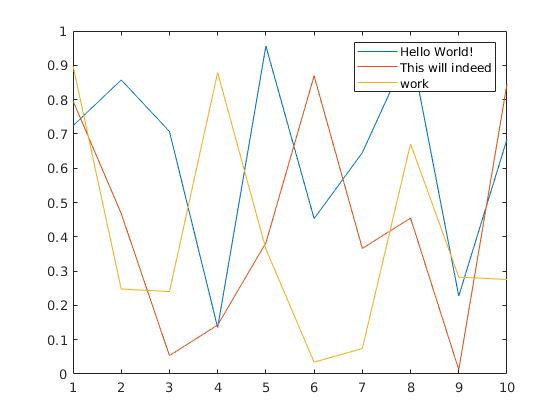

figure
plot(rand(10,3))
legend(works)

## Parsing

using strsplit, you can separate strings based on certain qualifications, most commonly whitespace.  This function is also compatible with regex.

% Note below that columns are concatenated into a single char vector.
s = ['The rain in Spain stays' sprintf('\n') 'mainly in the plain.']

s =     'The rain in Spain stays
     mainly in the plain.'


strsplit(s)

ans = 1×9 cell array
    {'The'}    {'rain'}    {'in'}    {'Spain'}    {'stays'}    {'mainly'}    {'in'}    {'the'}    {'plain.'}


strsplit(s,'n')

ans = 1×7 cell array
    {'The rai'}    {' i'}    {' Spai'}    {' stays↵mai'}    {'ly i'}    {' the plai'}    {'.'}


[cellArray, delimiters] = strsplit(s,{'n' 'h'})

cellArray = 1×9 cell array
    {'T'}    {'e rai'}    {' i'}    {' Spai'}    {' stays↵mai'}    {'ly i'}    {' t'}    {'e plai'}    {'.'}


delimiters = 1×8 cell array
    {'h'}    {'n'}    {'n'}    {'n'}    {'n'}    {'n'}    {'h'}    {'n'}


All of this can also be done using the new function split.  

split(s)

ans = 9×1 cell array
    {'The'   }
    {'rain'  }
    {'in'    }
    {'Spain' }
    {'stays' }
    {'mainly'}
    {'in'    }
    {'the'   }
    {'plain.'}


## Finding Substrings

In a similar fashion, you can search for patterns in strings using *strfind*.

s

s = The rain in Spain stays
mainly in the plain.

idx = strfind(s,'in')

idx =      7    10    16    27    32    42


vec = @(v) v(:);
s(vec([idx ; idx + 1]))

ans = inininininin

There are many more features and operations that one can do with strings and character arrays, and you are encouraged to look at the documentation if you are interested.

# Objects and Classes

MATLAB is an OOP language, the variety of toolboxes that MATLAB has (machine learning, filter, even fixed point numbers) are enclosed in classes. You might not need to write your own classes in your years of Cooper, but understanding how classes work in MATLAB would allow you to use those toolboxes effectively and efficiently. 

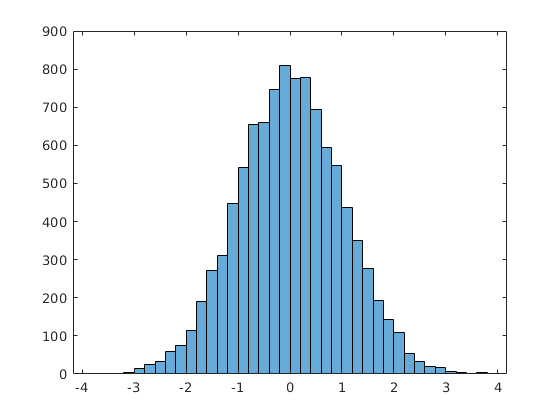

x = randn(10000,1);

h = histogram(x);

properties(h)


Properties for class matlab.graphics.chart.primitive.Histogram:

    Data
    BinCounts
    BinCountsMode
    NumBins
    BinEdges
    BinWidth
    BinMethod
    BinLimits
    BinLimitsMode
    Normalization
    FaceColor
    EdgeColor
    LineWidth
    LineStyle
    Orientation
    DisplayStyle
    FaceAlpha
    EdgeAlpha
    Values
    Children
    Parent
    Visible
    HandleVisibility
    DisplayName
    Annotation
    Selected
    SelectionHighlight
    HitTest
    PickableParts
    UIContextMenu
    ButtonDownFcn
    BusyAction
    BeingDeleted
    Interruptible
    CreateFcn
    DeleteFcn
    Type
    Tag
    UserData



methods(h)


Methods for class matlab.graphics.chart.primitive.Histogram:

Histogram       cat             eq              get             isprop          ne              vertcat         
addlistener     clo             fewerbins       getLayoutHints  java            reset           
addprop         double          findobj         horzcat         morebins        set             

Static methods:

loadobj         

Methods of matlab.graphics.chart.primitive.Histogram inherited from handle.



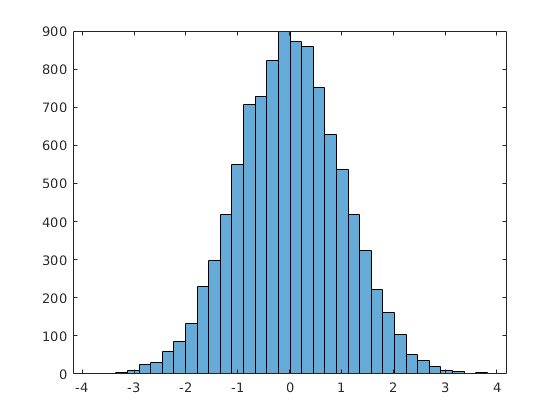

ans = 34

figure
h.fewerbins()

To write your own classes, you can use the syntax in *BasicClass.m*. 

## Structs vs Classes

Another way to group variables together in MATLAB are through structs. Structs are made out of field-value pairs, where each field's value is able to contain any type of data.

To make your own structs, you can do the following:

field1 = 'f1';  value1 = zeros(1,10);
field2 = 'f2';  value2 = {'a', 'b'};
field3 = 'f3';  value3 = {pi, pi.^2};
field4 = 'f4';  value4 = {'fourth'};
s = struct(field1,value1,field2,value2,field3,value3,field4,value4)
s(1)
s(2)